ds_rate={'ori','ds2','ds5','ds10','ds20','ds50','ds100'}

ds_rate = 1×7 cell 배열
    {'ori'}    {'ds2'}    {'ds5'}    {'ds10'}    {'ds20'}    {'ds50'}    {'ds100'}


s=1

s = 1

e=3000

e = 3000

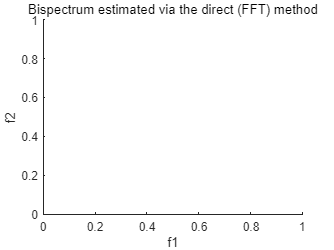

% cost=zeros(length(var_names),6)

% for k=1:length(var_names)
%     var_names{k}
    for i=1:length(ds_rate)
        %var_names{k}
        expression=strcat("rpm=","norm_45",".",ds_rate{i},"_rpm;");
        eval(expression);
        avg=mean(rpm);
        IASFR=rpm/avg;
        IASFR_sample=IASFR(s:e);
        IMF=zeros(6,length(IASFR_sample));
        IMF=emd(IASFR_sample,"MaxNumIMF",6);
        tmp=rica(IMF,3);
        ica=transform(tmp,IMF);
        [Bspec,waxis]=BISPECD(ica,1024,20,3,0);
        reduce_start=(length(Bspec)/2)-(length(Bspec)/20);
        reduce_end=(length(Bspec)/2)+(length(Bspec)/20);
        r_bispec=Bspec(reduce_start:reduce_end,reduce_start:reduce_end);
        r_bispec=r_bispec(round((length(r_bispec)/2)+1):round(length(r_bispec)),round((length(r_bispec)/2)+1):round(length(r_bispec)));
        len=length(r_bispec);
        r_bispec=abs(r_bispec);
        tr=zeros(1,length(r_bispec));

        for q= 1:len
            if q<=len/2
                for p=1:q
                    tr(q)=tr(q)+r_bispec(p,q);
                end
            elseif q>len/2
                for p=1:len-q
                    tr(q)=tr(q)+r_bispec(p,q);
                end
            end
        end


        expression=strcat("B",num2str(i),"=tr;");
        eval(expression);
    end


%     cost(k,1)=sum(abs(B1-B2));
%     cost(k,2)=sum(abs(B1-B3));
%     cost(k,3)=sum(abs(B1-B4));
%     cost(k,4)=sum(abs(B1-B5));
%     cost(k,5)=sum(abs(B1-B6));
%     cost(k,6)=sum(abs(B1-B7));


% end

qq=0.05

qq = 0.0500

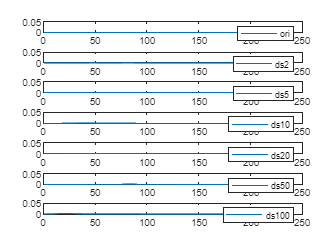

subplot(7,1,1)
plot(B1); 
legend('ori')
ylim([0,qq])

subplot(7,1,2)
plot(B2);
legend('ds2')
ylim([0,qq])

subplot(7,1,3)
plot(B3);
legend('ds5')
ylim([0,qq])

subplot(7,1,4)
plot(B4);
legend('ds10')
ylim([0,qq])

subplot(7,1,5)
plot(B5);
legend('ds20')
ylim([0,qq])

subplot(7,1,6)
plot(B6);
legend('ds50')
ylim([0,qq])

subplot(7,1,7)
plot(B7)
legend('ds100')
ylim([0,qq])

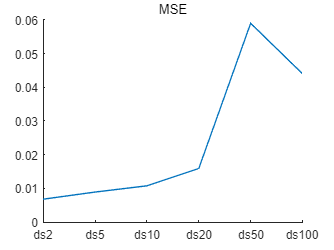

f2=figure;
cost(1)=sum(abs(B1-B2));
cost(2)=sum(abs(B1-B3));
cost(3)=sum(abs(B1-B4));
cost(4)=sum(abs(B1-B5));
cost(5)=sum(abs(B1-B6));
cost(6)=sum(abs(B1-B7));

% ty=rescale(cost)
% tt=rescale(cost_2)

hold on
plot(cost)
% plot(tt)

title('MSE')
xticks(1:1:6)
xticklabels({'ds2','ds5','ds10','ds20','ds50','ds100'})

% for i=1:6
%     cost(1,i)=mean(cost(:,i))
% end

% plot(cost(1,:))
% xticks(1:1:6)
% xticklabels({'ds2','ds5','ds10','ds20','ds50','ds100'})